# V768 - Measuring Vision with Psychophysics

## Lab 5 - Adaptive Methods

In the forced choiced experiments from previous labs, the levels of the independent variable(s) were chosen ahead of time, and you completed a fixed number of trials per condition. What if, instead, you wanted to make the levels of your independent variable depend on the participant's performance? In other words, what if you wanted the experiment to ***adapt*** to the participant?

This lab will introduce you to **adaptive methods** by walking you through the **staircase** experimental design. There are many different ways to design experiments with staircases, far too many to cover in one lab, so this lab will focus on building intuitions about the specific examples included here and some of the key considerations for staircase experiments.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Explain the motivations for the development of adaptive methods.

- Describe the differences between an experiment that uses the method of constant stimuli and one that uses an adaptive staircase method.

### Questions

- Why do some experiments require pairs of staircases, when others do not?

- What are the main motivations for using staircases instead of the method of constant stimuli?

- Include and write a caption for the second figure in Part C. Step 3. (Visualize your data; this figure has the two staircases separated.)

- When we fit a psychometric function to data collected using a staircase method, why do we use the log-likelihood cost function instead of the mean squared error?

- Include and write a caption for the second figure in Part C. Step 5. (Fit your data)

- What was the point of subjective equality (PSE) for your data? Do you think your data was biased? Why or why not?

- What was your just noticeable difference (JND)? Explain what that means in terms of what orientations you can and cannot discriminate.

## Part A. The Staircase Method

**Adaptive methods** allow the experimenter to efficiently measure an observer's perceptual threshold by adaptively adjusting the stimulus level based on the observer's performance. Often, using these methods reduces the number of trials that an observer needs to perform.

The core adaptive method is the **staircase**. There are many different ways that you can set up a staircase, but in this lab, we'll stick to staircase designs that adjust the difficulty of the task based on whether a participant's responses are correct or incorrect.

**How does a staircase work?** Imagine an actual staircase that starts at the easiest difficulty level and descends down toward a difficulty level where the task becomes effectively impossible (e.g., 100% contrast at the top of the staircase and 0% contrast at the bottom). In an experiment with a staircase design, the task difficulty will step up and down that staircase depending on the observer's responses.

The most common staircase design is the **1-up-N-down** staircase. After N **correct** responses, the stimulus level goes **down** by a step (i.e., difficulty *increases*). After 1 **incorrect** response, the stimulus level goes **up** by a step (i.e., difficulty *decreases*).

### Staircases for detection tasks

The **forced choice** tasks from previous labs measured how your ability to ***detect*** gratings changed depending on their contrast. In all of those experiments, the contrast levels had already been chosen, and your responses had no impact on the next trial's stimulus.

Let's say that we instead ran a contrast sensitivity experiment with a **1-up-2-down** staircase design. Below, you can see how that experiment might unfold over the course of 60 trials. The value of the independent variable (contrast) moves up and down as experiment progresses, drawing what looks like a staircase (granted, an unusually bumpy staircase). The value goes down when an observer responds correctly (black dot) two trials in a row, and the value goes up every time the observer responds incorrectly (red x).

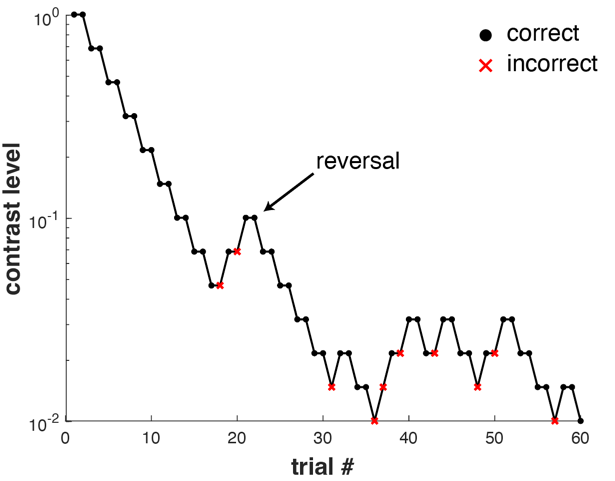

This is a typical way to visualize a staircase. You can easily see how the stimulus feature of interest changed over the course of the experiment. In this example, the stimulus level started high and gradually stepped downward until the observer responded incorrectly, which caused the direction of change to ***reverse*** and the stimulus level to step upward. Both incorrect responses and back-to-back correct responses caused the stimulus change to reverse direction.

The points where the direction of change reverses are known as **reversals**. We won't use reversals to analyze staircase data in this lab, but analyses in older papers often discuss and rely on reversal points.

### Staircases for discrimination tasks

Now, let's switch things up. Instead of a detection task, let's imagine running a **discrimination task**, and instead of trying to determine whether an observer saw a grating with a particular contrast, let's try to determine how well they can see a grating's ***orientation***.

To do that, we'll want to present the observer with two gratings on each trial: a **reference** grating and a **test** grating. We'll then want them to choose whether the test grating was rotated clockwise (CW) or counterclockwise (CCW), in comparison to the reference grating.

Instead of presenting the gratings on the left and right sides of the screen, let's present them in two different time intervals. In other words, let's make this a **two-interval forced choice (2IFC)** task. Each trial will consist of an initial 500 millisecond interval, a 100 ms gap (interstimulus interval, ISI), a second 500 ms interval, and a time window during which the observer must respond. We'll present the reference grating in the first time interval and the test grating in the second interval. The observer's task will then be to report whether the grating in the second interval was more clockwise or counterclockwise than the grating in the first interval.

As an example, here are two stimuli we could show. The first grating is straight up and down (vertical), and the second is rotated slightly to the left (counterclockwise). Thus, for a trial with these stimuli, counterclockwise would be the correct choice.

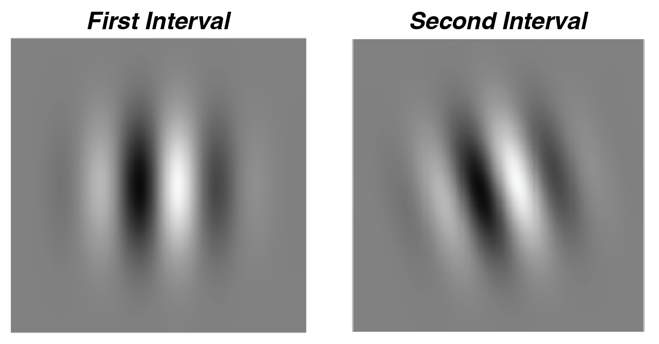

For this orientation discrimination experiment, the stimulus level that will increase and decrease is the **difference between the orientations** (specifically, the orientation shown in the 2nd interval minus the orientation shown in the 1st interval). When the orientation difference is positive, the correct answer is clockwise, and when the orientation difference is negative, the correct answer is counterclockwise. Below, you can see an example **1-up-2-down** staircase for this task.

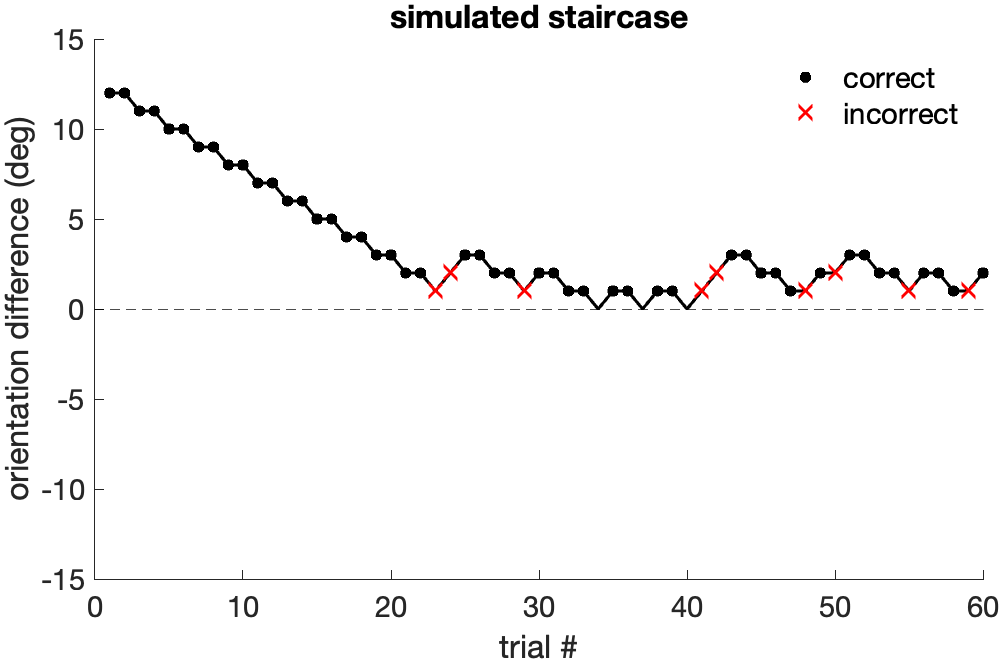

With a discrimination task, the bigger the ***absolute***** difference** between the two stimuli, the easier the trial. Thus, trials with an orientation difference of 10 and -10 will be relatively easy, and trials with an orientation difference of 1 and -1 will be relatively hard. This staircase starts with a positive difference and ends close to 0 (no difference), but what about the negative differences?

Again, imagine an actual staircase that starts at the easiest difficulty level and moves toward a difficulty level where the task becomes completely impossible. The staircase can only go as far as the observer's perception can take it, so the staircase can neither reach nor cross the impossible level. Therefore, to measure perception of negative differences, we need to have the observer complete a staircase that starts with a negative difference.

Discrimination experiments usually involve both **positive and negative differences** between the reference and test stimuli, so for discrimination experiments, staircases are usually completed in pairs: one that starts above 0 and one that starts below 0. For both staircases, the difficulty level will go up or down depending on the observer's responses.

Just as there are many different ways to design staircases, there are many possible ways to handle trials with no actual difference. For this lab, we'll treat it

For our orientation discrimination experiment, adding a negative-starting staircase would result in something like:

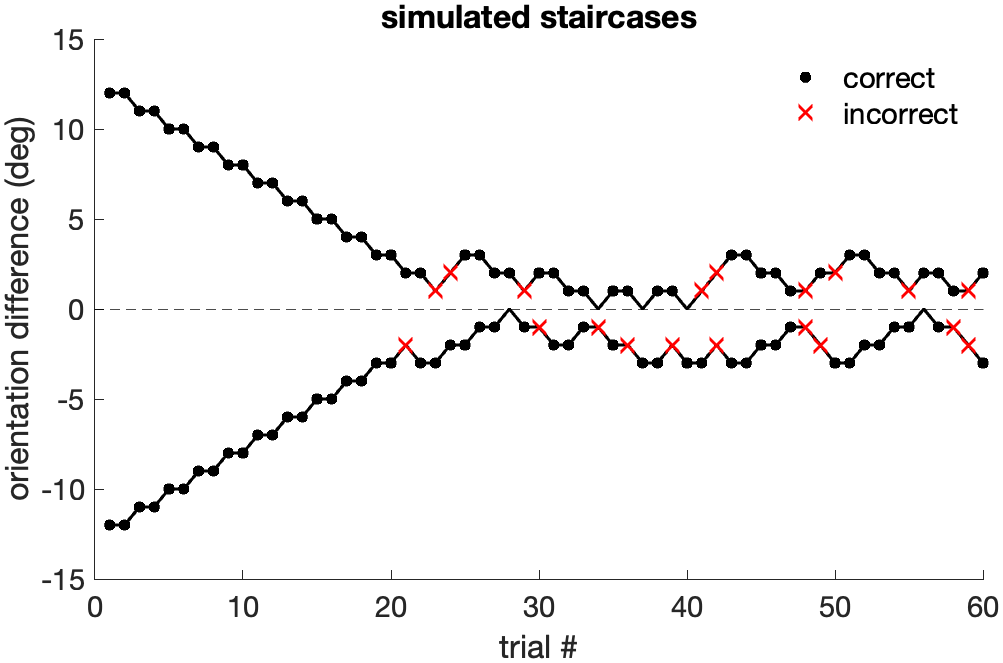

Because one starts above 0 and one starts below 0, these staircases move in different directions along the y-axis, but they both still follow the 1-up-2-down pattern in terms of difficulty level (i.e., proximity to 0).

### Psychometric curves for discrimination tasks

A psychometric curve has ***stimulus level*** on the x-axis and ***response probability*** on the y-axis. For our simple forced choice (yes-no) contrast detection task, the response probability that we plotted was the probability that the observer reported a stimulus was present. For our two-alternative forced choice (2AFC) task, the response probability that we plotted was the probability that the observer responded correctly. **What response probability should we plot for our orientation discrimination task?**

As we just covered, both very positive and very negative differences are "easy" to discriminate between. Therefore, plotting the probability of responding correctly will draw a v-like shape, like so:

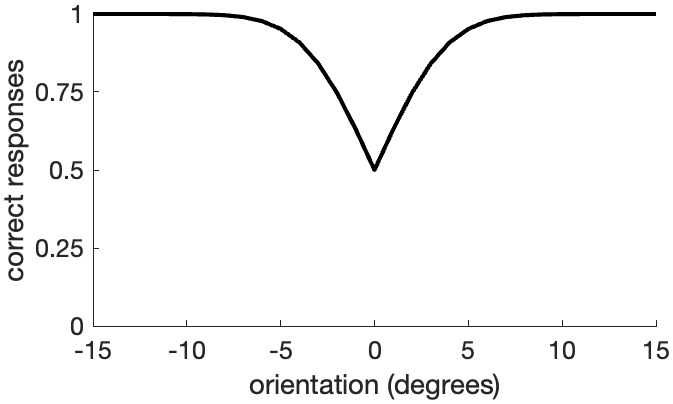

What if instead we plotted the probability of responding a certain way, like we did for our simple forced choice task? Let's think through how that could work.

- When the difference between stimuli is very negative, the probability of reporting that the difference was negative should be close to 1, and the probability of reporting that it was positive should be close to 0.

- When the difference between stimuli is very positive, the probability of reporting that the difference was negative should be close to 0, and the probability of reporting that it was positive should be close to 1.

Ideally, we want to plot a probability that is close to 0 when the difference between stimuli is very negative (left side of the plot) and close to 1 when the difference is very positive (right side of the plot). Therefore, plotting the **probability of reporting that the difference was *****positive*** seems like the better option.

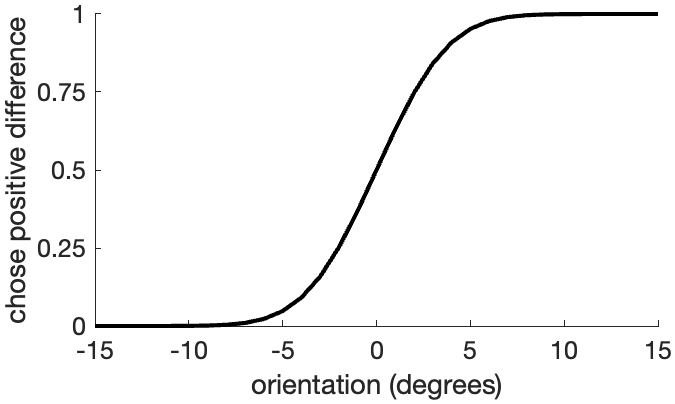

## Part B. Simulate an Orientation Discrimination Experiment

Now that we've covered some of the basics, let's build our intuitions about staircases by simulating an orientation discrimination experiment.

### Step 1. Choose parameters for your simulation

To determine how our simulated observer will perform on our discrimination task, we can (1) define their "true" psychometric function; (2) find the response probabilities for each of our stimulus levels; and (3) incorporate some variability to simulate the perceptual, decision-making, and motor noise that impacts observers' performance in real experiments.

The first step in that process is choosing a set of parameters for their psychometric curve.

% define psychometric function
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

% define parameters
sim_mu = 0;
sim_sigma = 3;
sim_guess_rate = 0;
sim_lapse_rate = 0;
sim_params = [sim_mu, sim_sigma, sim_guess_rate, sim_lapse_rate];

#### Visualize the psychometric curve

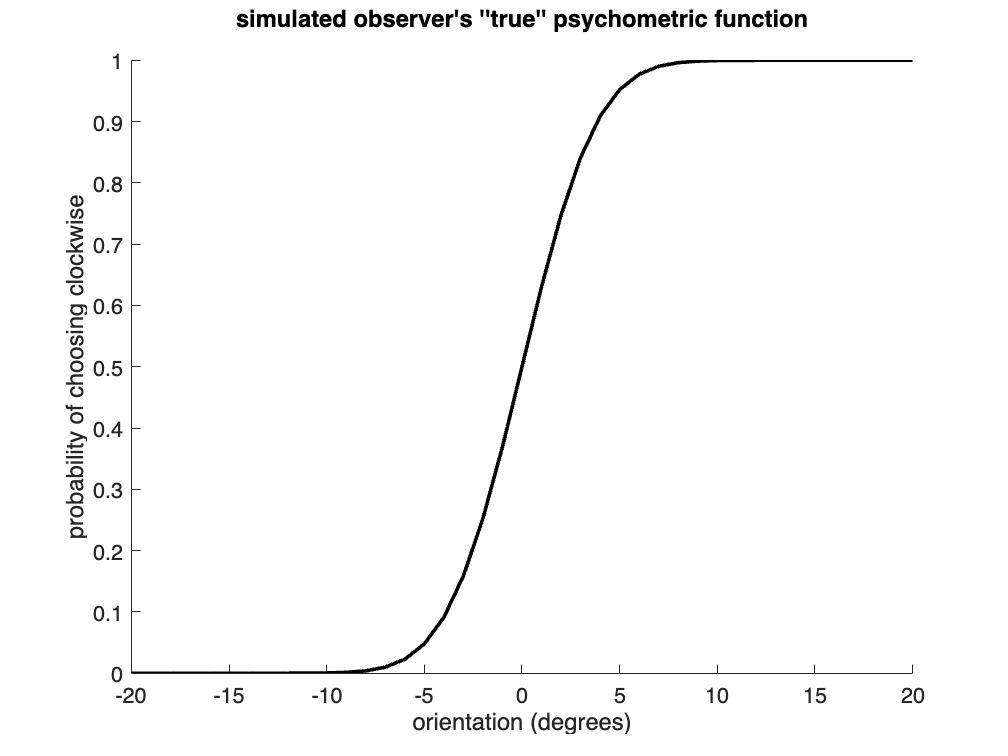

% get curve's x and y values
ori_axis = -20:20;
prob_axis = psyfxn(sim_params,ori_axis);

% plot curve
figure
plot(ori_axis,prob_axis,'k','LineWidth',2)
set(gca,'FontSize',12); box off
title(["simulated observer's ''true'' psychometric function",""])
xlabel("orientation (degrees)"); ylabel("probability of choosing clockwise");

drawnow

### Step 2. Simulate staircase trials

Now let's simulate trials for an orientation discrimination experiment with a 1-up-2-down staircase design.

For this simulation, we need to simulate one trial at a time because the orientation presented on a trial depends both on the previous orientation presented and on the observer's performance.

#### Incorporating response variability

By defining our simulated observer's psychometric function, we've already established what our observer's "true" performance on this task would be. However, we know that experimental results are impacted by perceptual, decision-making, and motor noise (and by practical considerations like the number of trials included). **How can we incorporate some variability into our observer's responses?**

Let's think about what we're trying to accomplish. For any given stimulus level, we can use our observer's psychometric function to find the "true" probability that they would choose clockwise (i.e., that the difference between stimuli was positive), and we want to use that to determine whether they responded clockwise or counterclockwise on a specific trial. Essentially, we want to be able to simulate a weighted coin flip on each trial. We can accomplish that by sampling from a **binomial distribution**.

Binomial distributions model the outcome of a set of independent events (trials), with each event having two possible outcomes: success or failure. These distributions have two parameters: the number of independent trials, $N$, and the probability of success, $p$. The probability of exactly $k$ successes out of $N$ trials is given by the binomial probability mass function:


$$f\left(k;N,p\right)=\Pr \left(X=k\right)=$$

$${N}\choose{k}$$

$$p^k \cdot (1-p)^{N-k}$$


If a random discrete variable $X$ is binomially distributed, this function allows you to calculate the probability that $X$ will be equal to $k$: $\Pr \left(X=k\right)$.

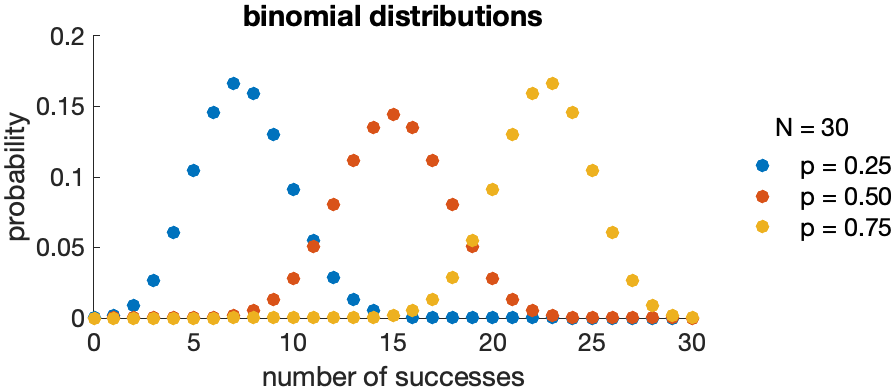

While distributions such as Gaussians are ***continuous***, the binomial distribution is ***discrete***. This means that a binomially distributed random variable $X$ can only ever be a countable number (a non-negative whole number: 0, 1, 2, 3, 4, etc.). You can only choose clockwise in an orientation discrimination task a discrete number of times, so the number of clockwise choices is a discrete variable.

If we have a single trial ($N=1$) with probability of success $p$, randomly sampling from the binomial distribution will give us a number of successes $k$. With only one trial in question, $k$ can only be 0 or 1, so sampling from the binomial distribution effectively simulates a weighted coin flip. That's exactly what we want to do when we simulate a discrimination trial!

#### Simulate a staircase

% define parameters for staircase
n_trials_per_staircase = 60;
initial_ori_diff = 12;  % degrees
staircase_step_size = 1;  % degrees

% set up stimulus and response vectors
stair_stim = nan(n_trials_per_staircase,1);
stair_resp = nan(n_trials_per_staircase,1);
stair_resp_correct = nan(n_trials_per_staircase,1);

% set initial stimulus condition
stair_stim(1) = initial_ori_diff;

% simulate trials
correct_counter = 0;
for ii=1:n_trials_per_staircase
    % get response probability for current trial
    p = psyfxn(sim_params, stair_stim(ii));

    % add randomness via the binomial distribution
    is_resp_cw = binornd(1,p);  % == 0 or 1
    stair_resp(ii) = is_resp_cw;

    % determine whether response was correct
    is_stim_cw = stair_stim(ii) > 0;
    is_stim_ccw = stair_stim(ii) < 0;
    is_resp_correct = (is_stim_cw & is_resp_cw) | (is_stim_ccw & ~is_resp_cw);
    stair_resp_correct(ii) = is_resp_correct;

    % determine condition for next trial
    if ii < n_trials_per_staircase
        if is_resp_correct  % chose correctly
            correct_counter = correct_counter + 1;
            if correct_counter == 2
                stair_stim(ii+1) = stair_stim(ii) - staircase_step_size;
                correct_counter = 0;  % reset
            else
                stair_stim(ii+1) = stair_stim(ii);
            end
        else  % chose incorrectly
            stair_stim(ii+1) = stair_stim(ii) + staircase_step_size;
            correct_counter = 0;  % reset
        end
    end
end

#### Visualize simulated staircase

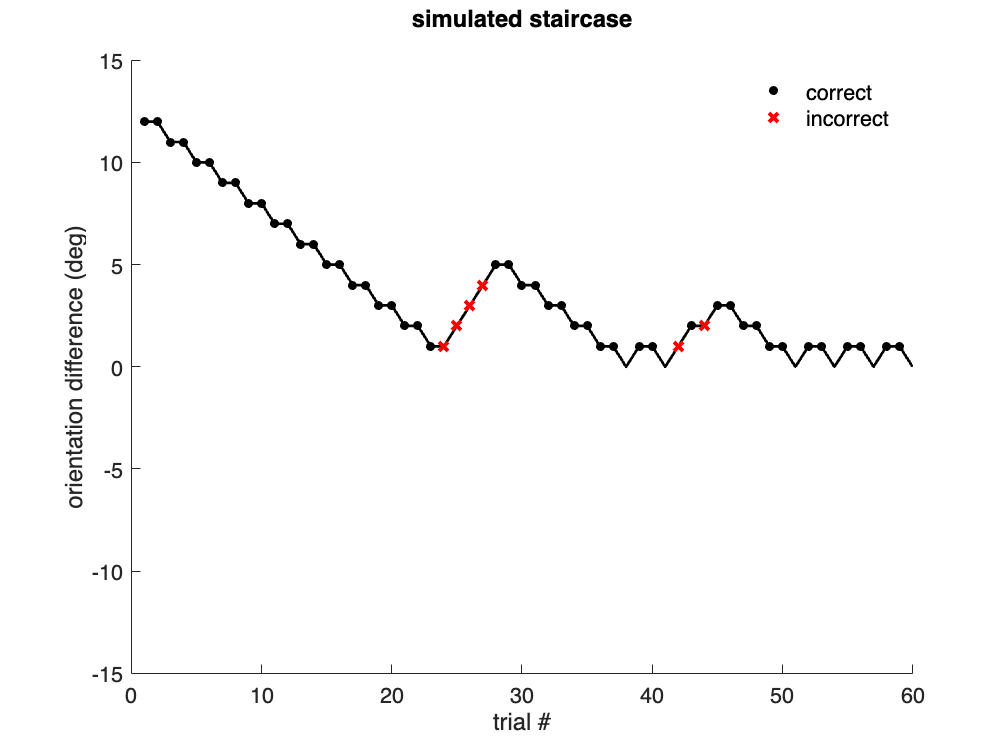

% plot stimulus levels
figure; hold on;
trial_nums = 1:n_trials_per_staircase;
plot(trial_nums, stair_stim, 'k','LineWidth',1.5)

% mark correct and incorrect responses
to_mark_correct = stair_resp_correct & (stair_stim ~= 0);
to_mark_incorrect = ~stair_resp_correct & (stair_stim ~= 0);
plot(trial_nums(to_mark_correct), stair_stim(to_mark_correct), ...
    'k.','MarkerSize',15)
plot(trial_nums(to_mark_incorrect), stair_stim(to_mark_incorrect), ...
    'rx','MarkerSize',7,'LineWidth',2)

set(gca,'FontSize',12); box off; ylim([-15,15])
title(["simulated staircase",""])
xlabel("trial #"); ylabel("orientation difference (deg)")
legend(["","correct","incorrect"], 'Box','off', 'FontSize',12)

drawnow

### Step 3. Simulate a second staircase

Recall that staircases for discrimination tasks are usually performed in pairs. Notice in the figure above that the staircase does not often go below 0 degrees. This second staircase will provide data for the lower part of the graph.

% change initial orientation difference
initial_ori_diff = -12;  % degrees

% set up stimulus and response vectors
stair2_stim = nan(n_trials_per_staircase,1);
stair2_resp = nan(n_trials_per_staircase,1);
stair2_resp_correct = nan(n_trials_per_staircase,1);

% set initial stimulus condition
stair2_stim(1) = initial_ori_diff;

% simulate trials
correct_counter = 0;
for ii=1:n_trials_per_staircase
    % get response probability for current trial
    p = psyfxn(sim_params, stair2_stim(ii));

    % add randomness via the binomial distribution
    is_resp_cw = binornd(1,p);  % == 0 or 1
    stair2_resp(ii) = is_resp_cw;

    % determine whether response was correct
    is_stim_cw = stair2_stim(ii) > 0;
    is_stim_ccw = stair2_stim(ii) < 0;
    is_resp_correct = (is_stim_cw & is_resp_cw) | (is_stim_ccw & ~is_resp_cw);
    stair2_resp_correct(ii) = is_resp_correct;
    
    % generate next trial
    if ii < n_trials_per_staircase
        if is_resp_correct  % chose correctly
            correct_counter = correct_counter + 1;
            if correct_counter == 2
                stair2_stim(ii+1) = stair2_stim(ii) + staircase_step_size;
                correct_counter = 0;  % reset
            else
                stair2_stim(ii+1) = stair2_stim(ii);
            end
        else  % chose incorrectly
            stair2_stim(ii+1) = stair2_stim(ii) - staircase_step_size;
            correct_counter = 0;  % reset
        end
    end
end

#### Visualize both staircases

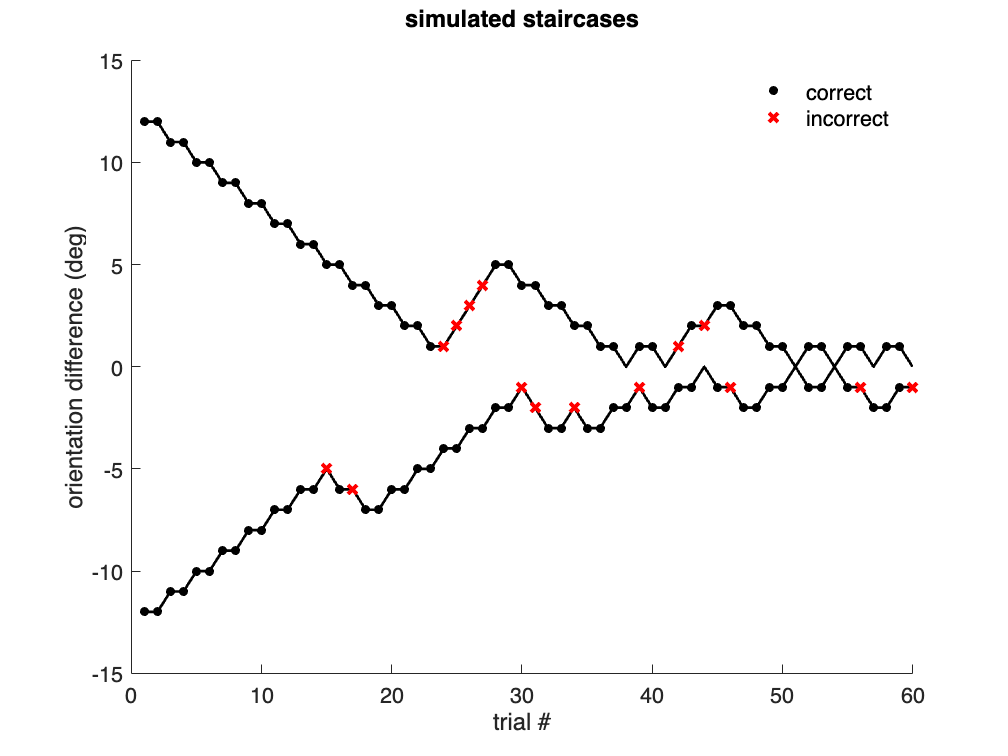

% plot first staircase
figure; hold on;
plot(trial_nums, stair_stim,'k','LineWidth',1.5)
to_mark_correct = stair_resp_correct & (stair_stim ~= 0);
to_mark_incorrect = ~stair_resp_correct & (stair_stim ~= 0);
plot(trial_nums(to_mark_correct), stair_stim(to_mark_correct), ...
    'k.','MarkerSize',15)
plot(trial_nums(to_mark_incorrect), stair_stim(to_mark_incorrect), ...
    'rx','MarkerSize',7,'LineWidth',2)

% plot second staircase
plot(trial_nums, stair2_stim,'k','LineWidth',1.5)
to_mark_correct = stair2_resp_correct & (stair2_stim ~= 0);
to_mark_incorrect = ~stair2_resp_correct & (stair2_stim ~= 0);
plot(trial_nums(to_mark_correct), stair2_stim(to_mark_correct), ...
    'k.','MarkerSize',15)
plot(trial_nums(to_mark_incorrect), stair2_stim(to_mark_incorrect), ...
    'rx','MarkerSize',7,'LineWidth',2)

set(gca,'FontSize',12); box off; ylim([-15,15])
title(["simulated staircases",""])
xlabel("trial #"); ylabel("orientation difference (deg)")
legend(["","correct","incorrect"], 'Box','off', 'FontSize',12)

drawnow

### Step 4. Analyze the results of the simulation

Even though we have collected this data in a somewhat different way than the method of constant stimuli, we can still use the psychometric function approach to analyze the data. 

**Note**: Historical papers using staircases will sometimes compute the average stimulus values from the "last n reversals" to measure threshold. This was a common approach to evaluating staircases in the past but it is no longer common practice and should be avoided.

#### Calculate response probabilities per condition

sim_results = array2table([[stair_stim; stair2_stim], [stair_resp; stair2_resp]],...
    "VariableNames",["orientation_level", "response"]);
sim_results = grpstats(sim_results, "orientation_level");
sim_results = renamevars(sim_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_clockwise"]);
sim_results.Properties.RowNames = {};
disp(sim_results)

    orientation_level    n_trials    prob_clockwise
    _________________    ________    ______________

           -12               2                0    
           -11               2                0    
           -10               2                0    
            -9               2                0    
            -8               2                0    
            -7               4                0    
            -6               6          0.16667    
            -5               3          0.33333    
            -4               2                0    
            -3               6                0    
            -2              12          0.16667    
            -1              14          0.35714    
             0               9          0.44444    
             1              15          0.86667    
             2               9          0.77778    
             

Note the range of trial counts per condition. Because we simulated an experiment with a staircase design, it's very unlikely that we'll end up with the same number of trials for each condition. This matters because more trials usually means more reliable data. Thus, for higher trial counts, we can be more certain that the probabilities we measured are close to the observer's "true" probability (how they would respond if there were no perceptual, decision, or motor noise making their performance vary trial-to-trial). On the other hand, if we only have a few trials for a condition, we can't trust that the probability we measured is "truthful", and we probably shouldn't let that data value have undue influence on our curve-fitting.

#### Plot performance

To visualize both the performance and number of trials per condition, let's make a bubble plot. A bubble plot is basically a scatterplot with dots (aka bubbles) of varying sizes. Typically, the size of the bubbles depends on the size of the sample that they represent. In this case, the larger the bubble, the more trials included for that condition.

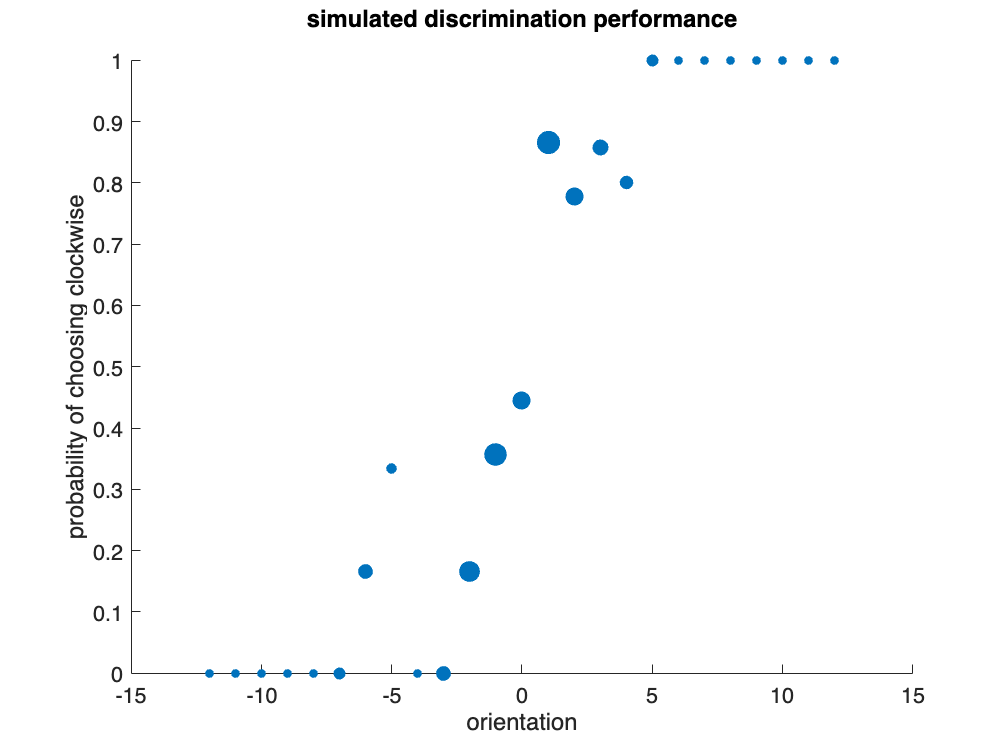

figure
scatter(sim_results.orientation_level, sim_results.prob_clockwise,...
    100*sim_results.n_trials, '.')
set(gca,'FontSize',12);
title(["simulated discrimination performance",""])
xlabel("orientation"); ylabel("probability of choosing clockwise");

drawnow

### Step 5. **Fit a psychometric curve**

#### The road so far

Let's recap some of what we've learned about curve-fitting. To start, we need the data we want to model, the function we want to fit to that data, and an initial guess for each of the function's parameter values ($\mu ,\sigma ,\gamma ,\lambda$). When we run an **optimization routine**, MATLAB will start by testing that combination of parameter values. To fit data, MATLAB will (1) find the curve produced by our psychometric function $\psi$, our stimulus levels $\mathbf{x}$, and the current set of parameter values; (2) compare that curve to the data; and (3) keep changing the parameter values until it finds a curve that's ***optimally*** close to the data (i.e., as close as MATLAB thinks it can find).

MATLAB determines how close our function's outputs are to our data points using a **cost function** (aka loss or error function). The further the curve is from the data, the higher the cost function's value will be. In other words, the cost function assigns a high cost to having a low goodness of fit. Since we want our goodness of fit to be as high as possible, we want to ***minimize*** the cost function's value.

Thus far, we've been using the MATLAB function `lsqcurvefit` to fit psychometric functions to data. That's `l` - `s` - `q` - `curve` - `fit`, which is short for **l**east-**sq**uares **curve**-**fit**ting. Least-squares refers to the cost function that `lsqcurvefit` uses (i.e., how it calculates goodness of fit). Not all of MATLAB's optimization functions have a built-in cost function, but `lsqcurvefit` does, which makes it a generally convenient option for curve-fitting. However, `lsqcurvefit`'s cost function weights all values equally, meaning that the difference between each data point and the curve has an equal impact on the cost function's value. That's great when we have an equal number of trials per condition, but staircase data usually has variable numbers of trials per condition, meaning that our confidence in the accuracy of each data point varies.

#### A new path forward

When fitting a function, an important consideration is whether or not you can have equal confidence in the accuracy of each of your data points. If you have any data points that have less supporting evidence (e.g., are calculated from fewer trials), you want them to have less of an impact on your the value of your cost function.

Therefore, for staircase data, we need to weight each value based on the corresponding number of trials. This means that we need to use a different MATLAB function to fit our data. Instead of using one with a built-in cost function, we want to use one that allows us to define our own cost function (which is an unnecessary inconvenience in simpler situations but a necessity with staircase data). That brings us to `fmincon`. That's f - `min` - `con`, which is short for **f**inding the **min**imum of a **con**strained multivariable function. You can read a little bit more about it in MATLAB's function documentation:

help fmincon

 fmincon finds a constrained minimum of a function of several variables.
    fmincon attempts to solve problems of the form:
     min F(X)  subject to:  A*X  <= B, Aeq*X  = Beq (linear constraints)
      X                     C(X) <= 0, Ceq(X) = 0   (nonlinear constraints)
                               LB <= X <= UB        (bounds)
     
    fmincon implements four different algorithms: interior point, SQP,
    active set, and trust region reflective. Choose one via the option
    Algorithm: for instance, to choose SQP, set OPTIONS =
    optimoptions('fmincon','Algorithm','sqp'), and then pass OPTIONS to
    fmincon.
                                                            
    X = fmincon(FUN,X0,A,B) starts at X0 and finds a minimum X to the 
    function FUN, subject to the linear inequalities A*X <= B. FUN accepts 
    input X and returns a scalar function value F evaluated at X. X0 may be
    a

Now we know what MATLAB function we need to use, but what cost function are we going to use?

#### Negative log-likelihood

In this lab, we're going to use a **negative log-likelihood** cost function.

**What is a likelihood? **Essentially, a likelihood value tells you how likely it is that a model generated your data. Psychometric functions are meant to model an observer's perception of a certain stimulus feature. More specifically, they model how the probability that an observer will respond a certain way changes as a function of the stimulus feature. In theory, the observer's performance on a task is a determined by their "true" psychometric function, with some variability mixed in due to perceptual, decision-making, and motor noise. Hence, when we're trying to fit a psychometric function to noisy response data, we are trying to find the "true" psychometric function that generated the data. To do that, it's useful to compute the **likelihood** that a function with a specific set of parameter values is the "true" function.

As an example, let's say that you ran an orientation discrimination task like the one we're simulating, and for trials with no orientation difference (0 degrees), you chose clockwise on 5 trials and counterclockwise on 5 trials. The probability that you chose clockwise is $5/10=0\ldotp 5$. A psychometric function that returns a probability of 0.2 at 0 degrees would be a poor match for your data, so the likelihood value associated with that point would be low. On the other hand, a psychometric function that returns a probability of 0.49 at 0 degrees would closely match your data, so the likelihood associated with that point would be high.

**Why log-likelihood?** Likelihood values often turn out to be tiny decimals (e.g., 0.00001), which can become difficult for the computer to deal with because of how computers internally represent numbers. So how can we decrease the amount of decimal places that our likelihood values have while maintaining the numbers' relative value? Taking the logarithm! It doesn't matter if we find the $\log_{10}$, the $\log_2$, or the $\ln$ (natural logarithm; $\log_e$) because the goal is just to end up with fewer decimal places to avoid running into trouble because of how computers work "under the hood".

(Reminder: $\log_{10} {\textrm{10}}^x =x$, so since $0\ldotp 00001={10}^{-5}$, $\log_{10} 0\ldotp 00001=-5$, converting a number with 5 decimal places to a whole number.)

**Why ****negative**** log-likelihood?** When we optimize a model (e.g., fit a psychometric curve), we want to **maximize**** the likelihood** of the observed data and **minimize**** the cost function**. Those are functionally equivalent, but in practice, we usually choose to have our optimization routine find parameters that minimize the cost function. (That's partially just for the practical reason that many optimization algorithms are built for minimization, not maximization.) As such, we flip the sign, making our log-likelihood negative.

**What negative log-likelihood cost function should I use? **Because the psychometric curve expresses probabilities for discrete events (trials), the appropriate likelihood function to use is the **binomial** probability function:


$${N}\choose{k}$$

$$p^k \cdot (1-p)^{N-k}$$


In this specific case, $p$ is the probability returned by the psychometric function for a particular orientation difference, given the current parameter values; $k$ is the number of trials reported clockwise; and $N$ is the total number of trials, meaning that $N-k$ is the number of trials reported counterclockwise.

This first component ${N}\choose{k}$ is a constant that makes sure the probability function sums to 1. In the context of optimization, we can ignore it. That leaves us with: $p^k \cdot (1-p)^{N-k}$. Take the log, and we end up with following log-likelihood function:


$$k\cdot \log(p) + (N-k)\cdot \log(1-p)$$


To calculate negative log-likelihood, we use that expression to calculate the log-likelihood of the psychometric function at each orientation level, sum over all those log-likelihoods, and multiply by -1.

As a MATLAB function, that looks like:

That function is saved in the file "negLogLikelihood.m" so that we can use it below.

**And how is all of this going to help me fit my data? **We needed to change our optimization procedure to account for the variable number of trials in staircase data. We had been using a cost function that weights all values equally. Using the negative log-likelihood as our cost function allows us to adjust the impact of each data point on our cost function's value. The more trials used to calculate a particular probability value in our data, the more weight that will be given to the goodness of fit at that point. This should help our optimization routine to fit our data more accurately, as it won't be "motivated" to change the parameters of the psychometric curve to make the curve match data points with low trial counts; instead, it'll focus on matching the curve to the data points with higher trial counts.

#### Fit the simulated data

% choose initial parameter values
init_params = [1, 5, .1, .1];

% fit psychometric curve to data
[fit_params, neg_log_likelihood] = fmincon(@(params) ...
    negLogLikelihood(params,...
    sim_results.orientation_level,...
    sim_results.prob_clockwise.*sim_results.n_trials,...
    sim_results.n_trials), init_params,...
    [],[],[],[],[-12,0,0,0],[12,100,.5,.5]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


MATLAB was able to reduce the value of our cost function to:

neg_log_likelihood

neg_log_likelihood = 47.3180

#### Assess parameter values

The table below shows both the true parameters of our observer's psychometric function and the best fit parameters returned by our optimization routine.

sim_param_table = array2table([sim_params; fit_params].', ...
    'RowNames',["mu","sigma","gamma","lambda"], 'VariableNames',["true","fit"]);
disp(sim_param_table)

              true       fit    
              ____    __________

    mu         0          0.1262
    sigma      3          2.3394
    gamma      0        0.054421
    lambda     0      1.1708e-06



**What do you notice?** How do the true and fit values compare?

**Plot both the simulated staircase data and the fitted curve**

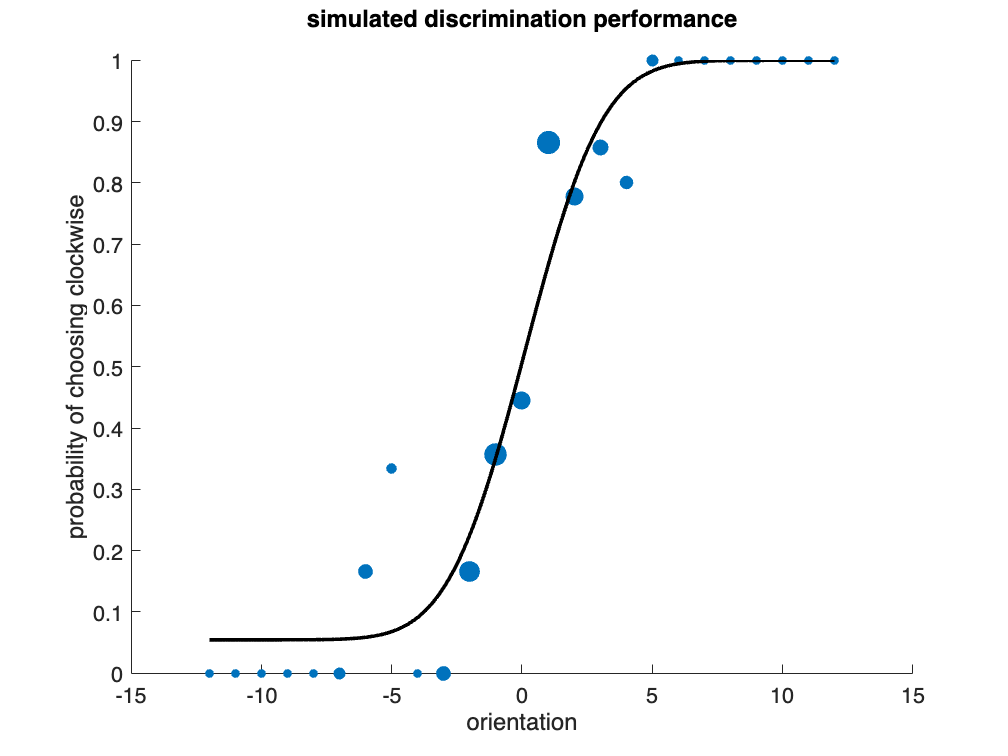

% get values for displaying fitted curve
xx = -12:.1:12;
yy = psyfxn(fit_params,xx);

% plot data and curve
figure; hold on;
scatter(sim_results.orientation_level, sim_results.prob_clockwise,...
    100*sim_results.n_trials, '.')
plot(xx,yy,'k','LineWidth',2)
set(gca,'FontSize',12)
title(["simulated discrimination performance",""])
xlabel("orientation"); ylabel("probability of choosing clockwise");

drawnow

**What do you think? **Is the curve a good model of our observer's data? Did the adjustment we made to our curve-fitting procedure work well?

#### Why use staircases?

Well, that took some extra work... Why did we decide to start thinking about negative log-likelihood? Oh right, because staircases.

**Why should we use staircases if that makes evaluating performance trickier? **Notice that we set our two staircases to run 60 trials each for a total of 120 trials. To run a comparable method of constant stimuli experiment, we would probably want to choose at least 9 orientation levels, and we would need at least 30 trials per point. That's a minimum of 270 trials, which is more than twice the staircase simulation. That means an actual experiment with a staircase design would take less than half the time!

**How is it possible to use fewer trials with a staircase?** We need more data where the psychometric function is changing (in the middle). The region where this occurs might be slightly different from across observers, so the staircase approach allows performance to dictate where we collect more data. We don't have to collect as much data because we don't collect as much data where performance is very obvious.

## Part C. Measure Orientation Discrimination 

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "adaptive-methods", and run that experiment. The experiment is a 2IFC orientation discrimination experiment. Your job on each trial will be to indicate whether the second interval gabor was tilted clockwise or counterclockwise relative to the first interval gabor. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 132 trials. 

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("adaptive-methods", "data");
if ~exist(data_dir, 'dir')
    error("PsychoPy data folder not found. Try changing your " + ...
        "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id+ "*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_05-adaptive-methods_2025-02-12_23h35.24.629.csv


#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
expt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    expt_data = [expt_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
expt_data(:,remove) = [];

% display data table size
n_trials = size(expt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 134


### Step 3. Visualize your data

For this experiment, the stimuli were gratings. The reference grating (shown in the first time interval) was always vertical (orientation = 0 degrees), and the orientation of the test grating (shown in the second time interval) varied across stimulus presentations.

For each trial, PsychoPy saved the difference in stimulus orientations and the response direction. The orientation difference was reported in degrees relative to vertical (e.g., 5 represents 5 degrees clockwise from vertical, and -10 represents 10 degrees counterclockwise from vertical). The responses were stored as either 'cw' (clockwise) or 'ccw' (counterclockwise).

% stash the stimulus orientation and response
stim_ori_diff = expt_data.staircase_intensity;
response_code = expt_data.response;

% convert to 1 for clockwise and 0 for counterclockwise
stim_dir = stim_ori_diff > 0;
response = strcmp(response_code,'cw');

% find zero diff trials
has_no_diff = stim_ori_diff == 0;

#### Determine whether responses were correct or incorrect

For a response to be correct, the participant's response must match the actual difference between the stimuli (i.e., both clockwise or both counterclockwise).

% determine whether responses were correct or incorrect
resp_correct = stim_dir == response;

% display overall performance (excluding 0 diff trials)
fprintf("overall percentage correct = %.2f%%\n", mean(resp_correct(~has_no_diff))*100);

overall percentage correct = 81.51%


#### Visualize the trials

Let's visualize the trials in this experiment by plotting the orientation of the second grating on each trial:

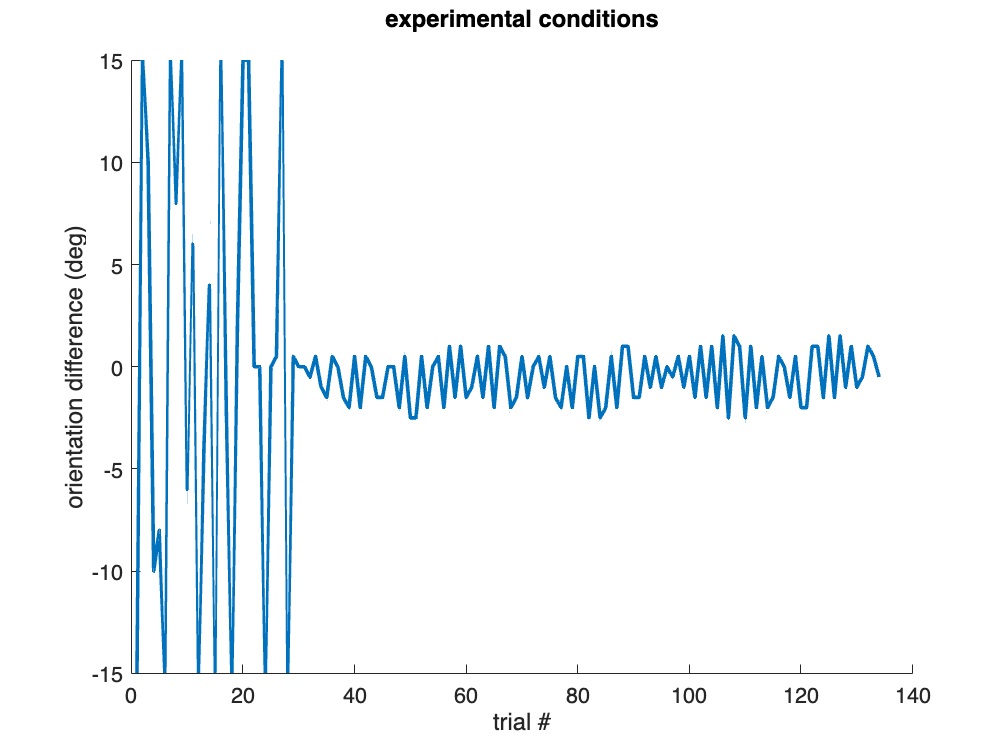

figure
plot(stim_ori_diff,'LineWidth',2)
set(gca,'FontSize',12); box off;
title(["experimental conditions",""])
xlabel("trial #"); ylabel("orientation difference (deg)")

drawnow

During the experiment, the trials from the positive and negative staircases were ***interleaved***, along with a handful of "easy trials". What we mean by interleaved is that we switched between two staircases during the experimental block, sometimes performing a trial from the first staircase and sometimes from the second staircase. Interleaving staircases is usually a good idea as it prevents participants from being able to track the progress of the staircase and use that information to help inform their decisions.

#### Visualize the staircases

To make these staircases look more like the visualization of our simulations, we have to plot the two staircases and the easy trials separately.

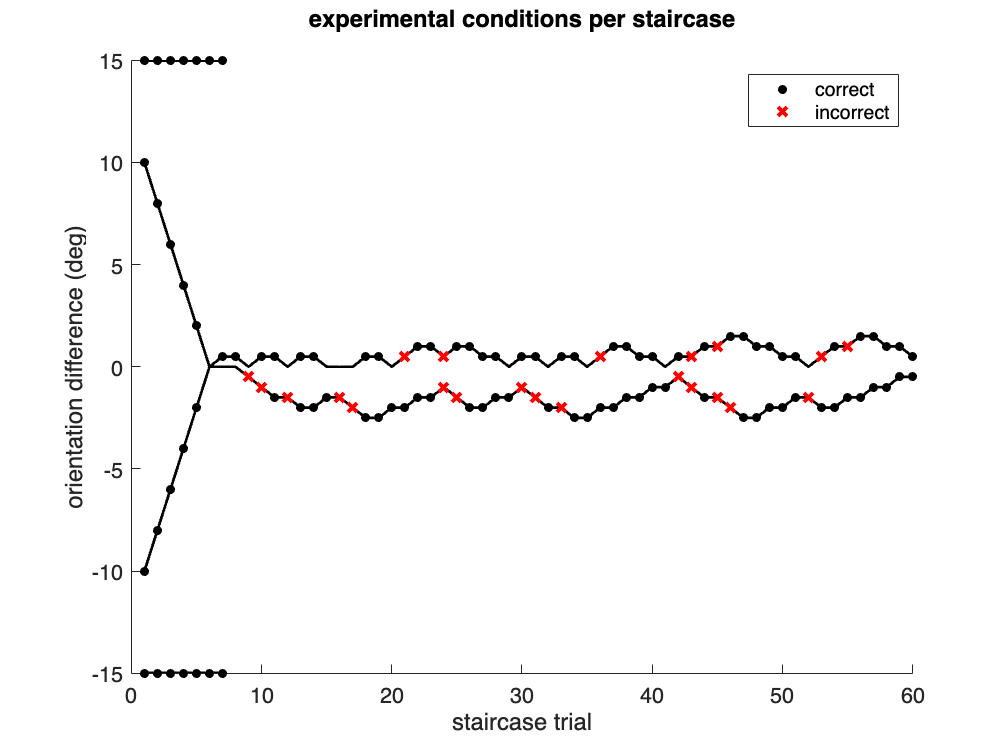

% find trials belonging to each staircase
which_staircase = expt_data.staircase_label;
idx_cw = strcmp(which_staircase,'cw');
idx_ccw = strcmp(which_staircase,'ccw');
idx_hi = strcmp(which_staircase,'hi');
idx_lo = strcmp(which_staircase,'lo');

% plot stimulus levels per staircase
figure; hold on;
plot(stim_ori_diff(idx_cw),'k','LineWidth',1.5)
plot(stim_ori_diff(idx_ccw),'k','LineWidth',1.5)
plot(stim_ori_diff(idx_hi),'k','LineWidth',2)
plot(stim_ori_diff(idx_lo),'k','LineWidth',2)

% plot responses
to_mark_correct = resp_correct & ~has_no_diff;
to_mark_incorrect = ~resp_correct & ~has_no_diff;
plot(expt_data.staircase_thisRepN(to_mark_correct), ...
    stim_ori_diff(to_mark_correct), 'k.','MarkerSize',15)
plot(expt_data.staircase_thisRepN(to_mark_incorrect), ...
    stim_ori_diff(to_mark_incorrect), 'rx','MarkerSize',7,'LineWidth',2)
set(gca,'FontSize',12)
title(["experimental conditions per staircase",""])
xlabel("staircase trial"); ylabel("orientation difference (deg)")
legend("","","","","correct","incorrect")

drawnow

Now you can see the two interleaved staircases and the handful of easy trials at -15 and +15 degrees.

**Why perform easy trials? **The staircases won't spend much time on the floor and the ceiling of the psychometric curve. These easy trials will make it easier for us to properly fit the guess rate ($\gamma$) and the lapse rate ($\lambda$).

### Step 4. Analyze your data

#### Determine percentage correct per condition

% average across responses per contrast level
analysis_table = table(response, expt_data.staircase_intensity, ...
    'VariableNames',["response", "orientation"]);
expt_results = grpstats(analysis_table, "orientation");
expt_results = renamevars(expt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_clockwise"]);
expt_results.Properties.RowNames = {};

% stash stimulus levels & counts
orientation_levels = unique(expt_results.orientation);
n_orientation = length(orientation_levels);

% display results
disp(expt_results)

    orientation    n_trials    prob_clockwise
    ___________    ________    ______________

        -15            7                0    
        -10            1                0    
         -8            1                0    
         -6            1                0    
         -4            1                0    
       -2.5            6                0    
         -2           17          0.17647    
       -1.5           18          0.33333    
         -1            8              0.5    
       -0.5            4              0.5    
          0           15              0.8    
        0.5           25              0.8    
          1           14          0.85714    
        1.5            4                1    
          2            1                1    
          4            1                1    
          6            1                1    
          8            

### Step 5. Fit your data

Using the same fitting procedure that we used for our simulated data, let's fit a psychometric curve to your data.

init_params = [0,1,0,0];

[expt_params, neg_log_likelihood] = fmincon(@(params) ...
    negLogLikelihood(params,...
    expt_results.orientation,...
    expt_results.prob_clockwise.*expt_results.n_trials,...
    expt_results.n_trials), init_params,...
    [],[],[],[],[-12,0,0,0],[12,100,.5,.5]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp(array2table(expt_params.', 'VariableNames',"fit", ...
    'RowNames',["mu","sigma","gamma","lambda"]))

                 fit    
              __________

    mu           -0.7767
    sigma         1.3534
    gamma     7.4862e-06
    lambda     9.991e-06



#### Plot performance and fitted curve

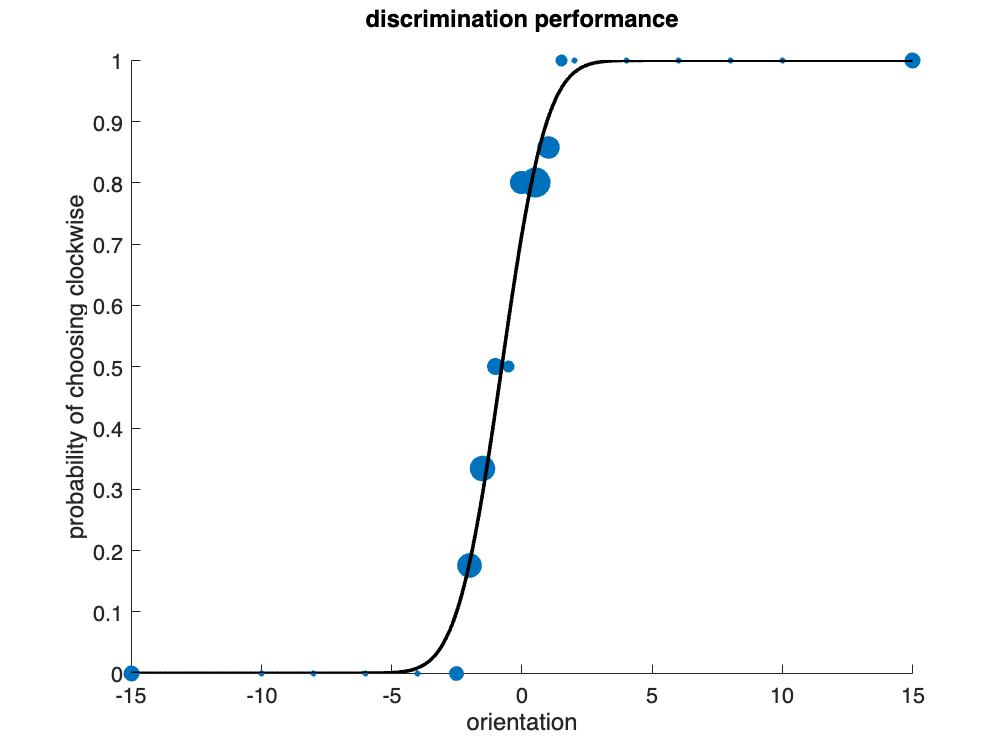

% get values for displaying fitted curve
xx = -15:.1:15;
yy = psyfxn(expt_params,xx);

% plot data and curve
figure; hold on;
scatter(expt_results.orientation,...
    expt_results.prob_clockwise,...
    100*expt_results.n_trials,...
    '.')
plot(xx,yy,'k','LineWidth',2)
set(gca,'FontSize',12)
title(["discrimination performance",""])
xlabel("orientation"); ylabel("probability of choosing clockwise");

drawnow

### Step 6. Make inferences from your data

There are a few important values that we can calculate to learn more about your performance in this experiment. One is the **point of subjective equality (PSE)**, which will tell us about the level of bias in your response (toward clockwise vs. counterclockwise). Another is the **just noticeable difference (JND)**, which tells us something about how precisely you can distinguish between different orientations.

#### Point of subjective equality (PSE)

In Lab 4, we used the inverse psychometric function to measure threshold, which allowed us to calculate sensitivity. Here, let's use it to calculate your PSE.

% define inverse psychometric function
ipsyfxn = @(c,p) norminv((p - c(3))/(1 - c(3) - c(4)), c(1), c(2));
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

pse = ipsyfxn(expt_params, .5)

pse = -0.7767

**What do you think?** Is your data biased?

#### Just noticeable difference (JND)

There are different ways to estimate your "true" JND. Here, let's calculate it based on your sigma value.

jnd = expt_params(2)/sqrt(2)

jnd = 0.9570

**What do you think?** Does that value match your expectations about the precision of your orientation perception?